# Cohcor

clear
Type = 'DPMS0T' ;
Materiau = '7075';
Eprouvette ='2';
Numero = '1';
addpath('/home/tdelaselle/Documents/Codes/Codes persos Matlab/Fonctions');
repertoire = acces_donnees_traitees();
addpath(strcat(repertoire,'/',Type,'/',Materiau,'/'));
Naming = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);  

% Parametres d'import
opts = delimitedTextImportOptions('DataLines',4,'Delimiter',' ','ConsecutiveDelimitersRule','join','VariableNamesLine',3);
COCO = readtable(strcat(Naming,'_cohcor.txt'),opts);


% Suppression de la 1ere variable
COCO.Var1 = [];

% Conversion des types 'string' en 'double'
len = size(COCO);
for i=1:(len(2))
    COCO.(i) = str2double(COCO.(i));
end

% Table triée par channel
COCO = sortrows(COCO,3);

% Suppression des lignes avec NaN
COCO = rmmissing(COCO);
len = size(COCO);

## Affichage cohérence et corrélation

affi = true;
nbreCh = 1;
Analyse = 'Les deux';

Affichage : 

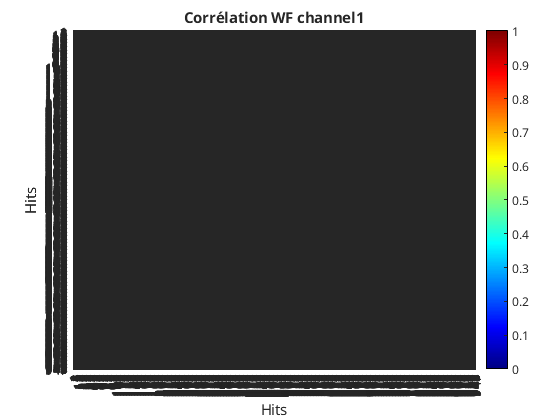

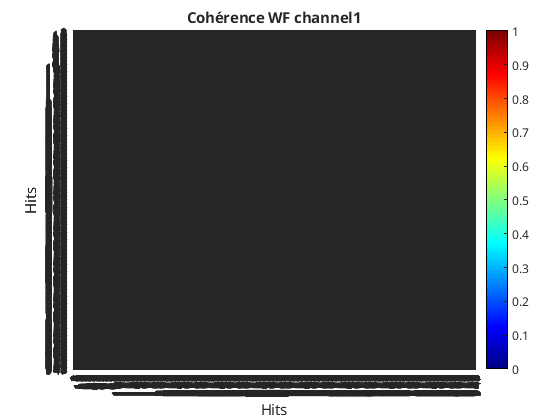

graphi = 'Matcol';
vue = 3;
zlimit = 0;

% Création et affichage des matrices corrélation/cohérence
if affi == 1
    figure();
    if strcmp(Analyse,'Corrélation') || strcmp(Analyse,'Les deux')
        A = zeros(max(COCO.Ev2),max(COCO.Ev2));
        COR = {A,A,A,A};
        k = 1;
        for i = 1:nbreCh
            while k<=len(1) && isequal(COCO.Ch(k),i)
                A(COCO.Ev1(k),COCO.Ev2(k)) = COCO.Cor(k);
                k = k+1;
            end
            A(isnan(A)) = 0;
            COR(i) = {A};
            if strcmp(graphi,'Histo3')
                Z = magic(1);
                b = bar3(COR{1,i});
                zlim([zlimit,1]);
                colorbar
                for t = 1:length(b)
                    zdata = b(t).ZData;
                    b(t).CData = zdata;
                    b(t).FaceColor = 'interp';
                end
                title(strcat('Corrélation WF channel ',' ',string(i)));
                xlabel('Hits');
                ylabel('Hits');
                zlabel('Corrélation');
                caxis([0 1]);
                view(vue);
                figure();
            end
            if strcmp(graphi,'Matcol')
                heatmap(COR{1,i});
                colormap jet;
                title(strcat('Corrélation WF channel ',' ',string(i)));
                xlabel('Hits');
                ylabel('Hits');
                caxis([0 1]);
                figure();
            end
            
        end
    end
    
    if strcmp(Analyse,'Cohérence') || strcmp(Analyse,'Les deux')
        A = zeros(max(COCO.Ev2),max(COCO.Ev2));
        COH = {A,A,A,A};
        k = 1;
        for i = 1:nbreCh
            while k<=len(1) && isequal(COCO.Ch(k),i) 
                A(COCO.Ev1(k),COCO.Ev2(k)) = COCO.Coh(k);
                k = k+1;
            end
            if i == 1
               kstock = k;
               if k > len(1)
                   kstock = kstock-1;
               end
            end
            A(isnan(A)) = 0;
            COH(i) = {A};
            if strcmp(graphi,'Histo3')
                Z = magic(5);
                b = bar3(COH{1,i});
                zlim([zlimit,1]);
                colorbar
                for t = 1:length(b)
                    zdata = b(t).ZData;
                    b(t).CData = zdata;
                    b(t).FaceColor = 'interp';
                end
                title(strcat('Cohérence WF channel ',' ',string(i)));
                xlabel('Hits');
                ylabel('Hits');
                zlabel('Cohérence');
                view(vue);
                caxis([0 1]);
                figure();
            end
            if strcmp(graphi,'Matcol')
                heatmap(COH{1,i});
                colormap jet;
                title(strcat('Cohérence WF channel ',' ',string(i)));
                xlabel('Hits');
                ylabel('Hits');
                caxis([0 1]);
                figure();
            end
        end
    end
end

Table des valeurs moyennes :

chtable = [1; 2];
% COCO2 = COCO;
% COCO2(:,isnan(COCO2.Cor)) = [];
cohmoy = [sum(COCO.Coh(1:kstock)/kstock); sum(COCO.Coh((kstock+1):len(1))/(len(1)-kstock))];
cormoy = [sum(COCO.Cor(1:kstock)/kstock); sum(COCO.Cor((kstock+1):len(1))/(len(1)-kstock))];
MOY = table(chtable,cohmoy,cormoy,'VariableNames',{'Ch', 'COHmoyenne', 'CORmoyenne'})

MOY = 2×3 table
    Ch    COHmoyenne    CORmoyenne
    __    __________    __________

    1      0.65699        0.6666  
    2      0.80484       0.77253  


Nombre de corrélations/cohérences au dessus d'un seuil : 

seuil = 0.95;
cohseuil = [0;0];
corseuil = [0;0];
for i = 1:kstock
    if COCO.Cor(i) >= seuil
        corseuil(1) = corseuil(1)+1;
    end
    if COCO.Coh(i) >= seuil
        cohseuil(1) = cohseuil(1)+1;
    end
end
for i = (kstock+1):len(1)
    if COCO.Cor(i) >= seuil
        corseuil(2) = corseuil(2)+1;
    end
    if COCO.Coh(i) >= seuil
        cohseuil(2) = cohseuil(2)+1;
    end
end
nbseuil = table(chtable,cohseuil,corseuil,'VariableNames',{'Ch', 'Nbre coh > seuil', 'Nbre cor > seuil'})

nbseuil = 2×3 table
    Ch    Nbre coh > seuil    Nbre cor > seuil
    __    ________________    ________________

    1              6863                8989   
    2        1.3463e+05          1.7227e+05   


## Détection multiplets

Paramètres

multi = false;
Seuil = 0.95;
metho = "Corrélation";
dt =  45.9;

if multi == 1
    MUL = COCO; 
    coc = table2array(COCO);
    t = 0;
    ch1 = 0;
    len = size(MUL);
    for i = 1:len(1)
        if metho == "Corrélation"
            if (coc(i,8) >= Seuil) && (abs(coc(i,5)-coc(i,9)) < dt)
                t = t+1;
                if coc(i,3) == 1
                    ch1 = ch1+1;
                end
                MUL(t,:) = COCO(i,:);
            end
        end
        if metho == "Cohérence"
            if (coc(i,4) >= Seuil) && (abs(coc(i,5)-coc(i,9)) < dt)
                t = t+1;
                MUL(t,:) = coc(i,:);
                if coc(i,3) == 1
                    ch1 = ch1+1;
                end
            end
        end
        if metho == "Les 2"
            if (coc(i,8) >= Seuil) && (coc(i,4) >= Seuil) && (abs(coc(i,5)-coc(i,9)) < dt)
                t = t+1;
                MUL(t,:) = COCO(i,:);
                if coc(i,3) == 1
                    ch1 = ch1+1;
                end

            end
        end
        if metho == "Une des 2"
            if (coc(i,4) >= Seuil) || (coc(i,8) >= Seuil) && (abs(coc(i,5)-coc(i,9)) < dt)
                t = t+1;
                MUL(t,:) = coc(i,:);
                if coc(i,3) == 1
                    ch1 = ch1+1;
                end

            end
        end
    end
    MUL1 = MUL(1:ch1,:);
    MUL2 = MUL((ch1+1):t,:);
%     for i = len(1):-1:t
%         MUL1(i,:) = [];
%     end
end     
    

## Affichage multiplets

if multi == 1
    choixCh = 2;
    graphi = 'Graph';
    % Création et affichage des matrices corrélation/cohérence
    if strcmp(graphi,'Hist')
        if choixCh == 1
            histogram([MUL1.Ev1 MUL1.Ev2],'BinWidth',0.99);
            title(strcat('Répartition des liens entre WFs du channel 1'));
            xlabel('Hits');
            ylabel('Nombre de liens avec WFs');
            figure();
        else
            histogram([MUL2.Ev1 MUL2.Ev2],'BinWidth',0.99);
            title(strcat('Répartition des liens entre WFs du channel 2'));
            xlabel('Hits');
            ylabel('Nombre de liens avec WFs');
            figure();
        end
    end
   if strcmp(graphi,'Graph')
       if choixCh == 1
            G = graph(string(MUL1.Ev1),string(MUL1.Ev2),(MUL1.Coh+MUL1.Cor));
            LWidths = 2*(G.Edges.Weight/max(G.Edges.Weight)).^10000;
            P = plot(G,'LineWidth',LWidths,'Layout','force');
            P.Marker = '.';
            P.NodeColor = 'r';
            P.MarkerSize = 7;
            P.LineStyle = "-";
            title(strcat('Représentation des liens entre WFs du channel 1'));
            figure();
       else
            G = graph(string(MUL2.Ev1),string(MUL2.Ev2),(MUL2.Coh+MUL2.Cor));
            LWidths = 2*(G.Edges.Weight/max(G.Edges.Weight)).^1000;
            P = plot(G,'LineWidth',LWidths,'Layout','force');
            P.Marker = '.';
            P.NodeColor = 'r';
            P.MarkerSize = 7;
            P.LineStyle = "-";
            title(strcat('Représentation des liens entre WFs du channel 2'));
            figure();
       end 
   end
end

histogram([MUL1.Ev1 MUL1.Ev2],'BinWidth',0.99);

Unable to resolve the name MUL1.Ev1.

% G = graph(string(MUL1.Ev1),string(MUL1.Ev2),MUL1.Coh);
% LWidths = 5*(G.Edges.Weight/max(G.Edges.Weight)).^500;
% P = plot(G,'LineWidth',LWidths);
% P.Marker = '*';
% P.NodeColor = 'r';
% P.MarkerSize = 10;

#### Waveforms superposées

load(strcat(Naming,'.mat'));
figure();
plot(WF.Temps,WF.('2_177'));

hold on
for a=178:188
    plot(WF.Temps-COCO.DTcoh(54103+a-178)/(5e6),WF.(strcat('2_',string(a)))*COCO.rEv1Ev2(54103+a-178));
end
hold off
xlabel({'Temps';'secondes'})
ylabel({'Amplitude';'volts'})
title(strcat("Superposition des waveforms du multiplet 2"))
xlim([-0.000008 0.00004])
legend("177","178","179","180","181","182","183","184","185","186","187","188")

figure();
plot(WF.Temps,WF.('2_22'));
hold on
for a=23:116
    plot(WF.Temps-COCO.DTcoh(32713+a-23)/(5e6),WF.(strcat('2_',string(a)))*COCO.rEv1Ev2(32713+a-23));
end
hold off
xlabel({'Temps';'secondes'})
ylabel({'Amplitude';'volts'})
title(strcat("Superposition des waveforms du multiplet 1"))
xlim([-0.000005 0.00005])

% figure();
% % for a=22:32
% %     plot(WF.Temps+COCO.DTcoh(54103+a-178)/(5e6),WF.(strcat('2_',string(a)))*COCO.rEv1Ev2(54103+a-178));
% % end
% hold on
% plot(WF.Temps,WF.("2_178"));
% plot(WF.Temps+5e-6,WF.("2_177"));
% plot(WF.Temps+0.5e-6,WF.("2_179"));
% plot(WF.Temps,WF.("2_180"));
% plot(WF.Temps+2e-6,WF.("2_181"));
% plot(WF.Temps+3.5e-6,WF.("2_182"));
% plot(WF.Temps+1.8e-6,WF.("2_183"));
% plot(WF.Temps+1.8e-6,WF.("2_184"));
% plot(WF.Temps+1.8e-6,WF.("2_185"));
% plot(WF.Temps+3.5e-6,WF.("2_186"));
% plot(WF.Temps+1.8e-6,WF.("2_187"));
% plot(WF.Temps,WF.("2_188"));
% hold off
% xlabel({'Temps';'secondes'})
% ylabel({'Amplitude';'volts'})
% title(strcat("Superposition des waveforms du multiplet 2"))
% xlim([-0.000005 0.00005])
% legend("177","178","179","180","181","182","183","184","185","186","187","188")

% figure();
% % for a=22:32
% %     plot(WF.Temps+COCO.DTcoh(54103+a-178)/(5e6),WF.(strcat('2_',string(a)))*COCO.rEv1Ev2(54103+a-178));
% % end
% hold on
% plot(WF.Temps,WF.("2_22"));
% plot(WF.Temps+0.010320900000000e-7,WF.("2_23"));
% plot(WF.Temps+1.07758700000000e-7,WF.("2_24"));
% plot(WF.Temps,WF.("2_25"));
% plot(WF.Temps,WF.("2_26"));
% plot(WF.Temps,WF.("2_27"));
% % plot(WF.Temps+1.8e-6,WF.("2_183"));
% % plot(WF.Temps+1.8e-6,WF.("2_184"));
% % plot(WF.Temps+1.8e-6,WF.("2_185"));
% % plot(WF.Temps+3.5e-6,WF.("2_186"));
% % plot(WF.Temps+1.8e-6,WF.("2_187"));
% % plot(WF.Temps,WF.("2_188"));
% hold off
% xlabel({'Temps';'secondes'})
% ylabel({'Amplitude';'volts'})
% title(strcat("Superposition des waveforms du multiplet 2"))
% xlim([-0.000005 0.00007])
% legend("177","178","179","180","181","182","183","184","185","186","187","188")